# ______________Computational Electromagnetics 

## _______________________________ Hw8-Q1

______________________Mohammadreza Arani         :::::::::::::         810100511

 __________________________________________1401/10/26


clear; close all; clc;

The problem is illustrated in figure below:

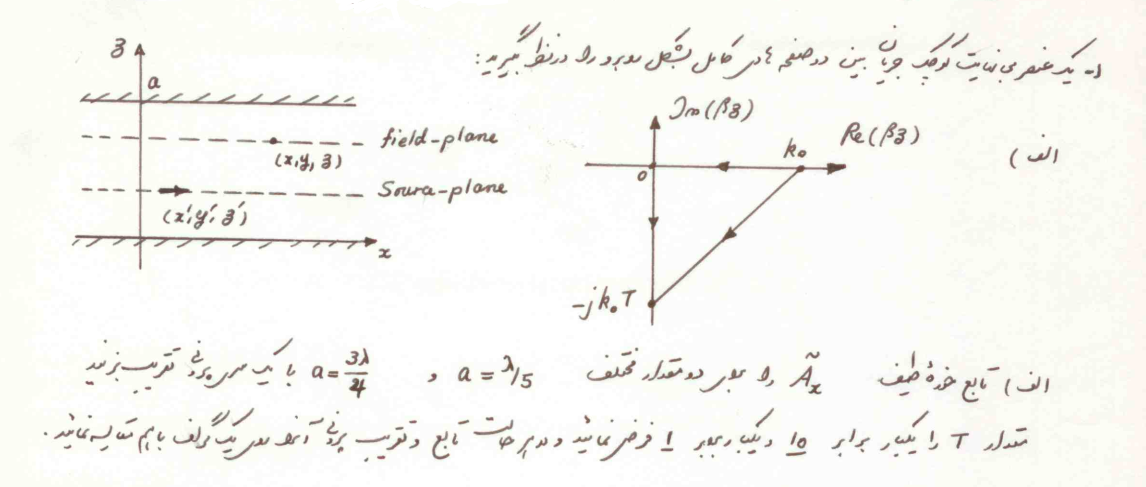

fc = 175e+06;
c  = 3e+08;
Lambda = c/fc;
K = 2*pi/Lambda;


T = 1;
a = Lambda/5;

syms Beta_z
F(Beta_z)  =  exp(-1j*Beta_z*2*a) ./ ( 1- exp(-1j*Beta_z*2*a) )  ; 


## Sampling From Function + Find Alphas

M  = 10;
t  = linspace(0,T,2*M); 
L1 = length(t);

B_Z = K*( (1-t/T) - 1j*t  ) ;

for i=1:L1
    F_B_z  =  double( F(B_Z) ) ;
end

Coeff_Alpha = zeros(M,M);

for p=1:M

    Coeff_Alpha(p,:) = -flip(F_B_z(1+p-1:M+p-1)) ;

end
Sampled_Points = F_B_z(M+1:2*M)';
Alpha          = inv(Coeff_Alpha)*Sampled_Points  ;


## Find Roots ($\mu$) + Find $a_m$


Mu = roots([1 ; Alpha]);
B_m  = log(Mu);

Coeff_A = zeros(2*M,M);
X_vec =B_Z ;

for p=1:2*M
    Coeff_A(p,:) = (Mu.^(X_vec(p))).*ones(M,1) ;
end

Sampled_Points_2 = F_B_z(1:2*M)'; 
A = pinv(Coeff_A)*Sampled_Points_2;


## Plotting Spectral Domain Form and Its Approximation

Beta = 0.001:0.01:10*Lambda;
z_point = 0.8*a;         % An example
z_point_source  = 0.1*a; % An example
M = 3;

T = 1;
a = Lambda/5;
Solution_1 = Solution_calc(M,T,a,K,Lambda,z_point,z_point_source,Beta);


T = 1;
a = 3*Lambda/4;
Solution_2 = Solution_calc(M,T,a,K,Lambda,z_point,z_point_source,Beta);

T = 10;
a = Lambda/5;
Solution_3 = Solution_calc(M,T,a,K,Lambda,z_point,z_point_source,Beta);


T = 10;
a = 3*Lambda/4;
Solution_4 = Solution_calc(M,T,a,K,Lambda,z_point,z_point_source,Beta);

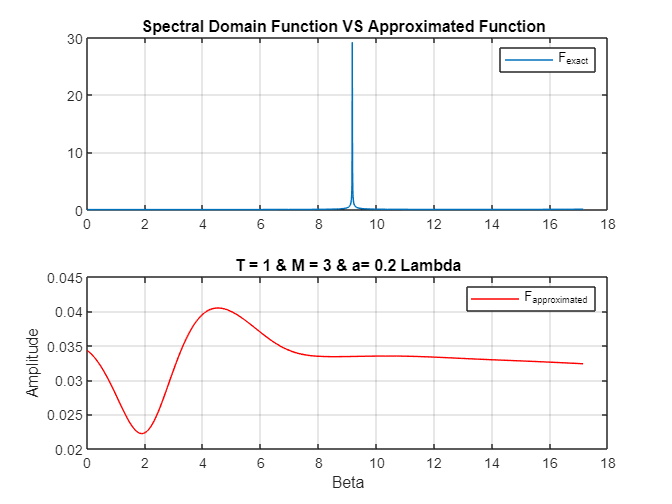

Plott_Compare(Solution_1.Beta,Solution_1.F_exact,Solution_1.F_approx,Solution_1.T,Solution_1.a,Solution_1.Lambda,Solution_1.M)

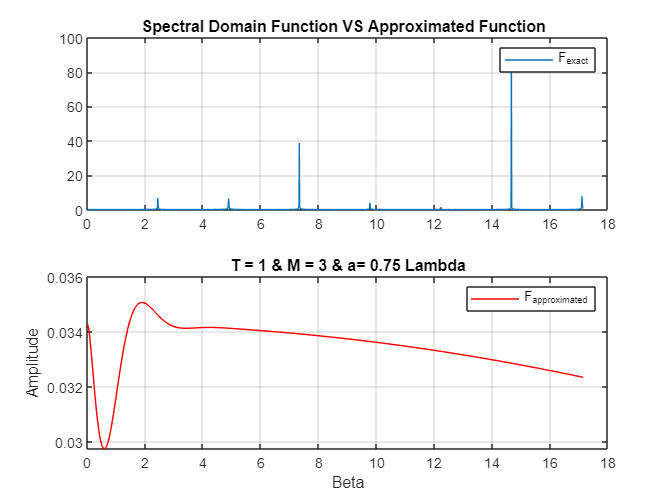

Plott_Compare(Solution_2.Beta,Solution_2.F_exact,Solution_2.F_approx,Solution_2.T,Solution_2.a,Solution_2.Lambda,Solution_2.M)

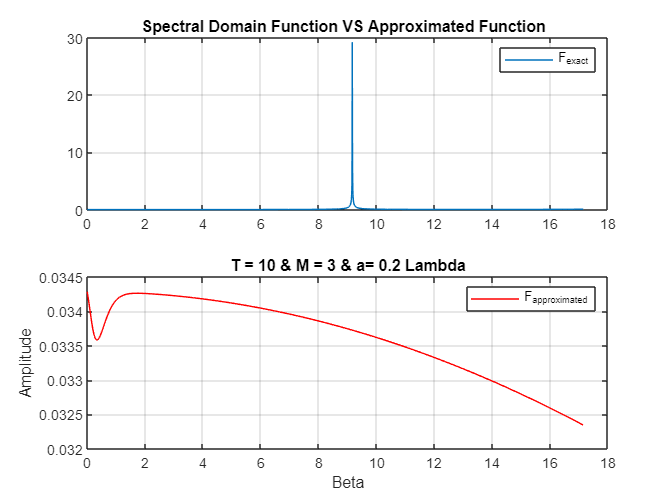

Plott_Compare(Solution_3.Beta,Solution_3.F_exact,Solution_3.F_approx,Solution_3.T,Solution_3.a,Solution_3.Lambda,Solution_3.M)

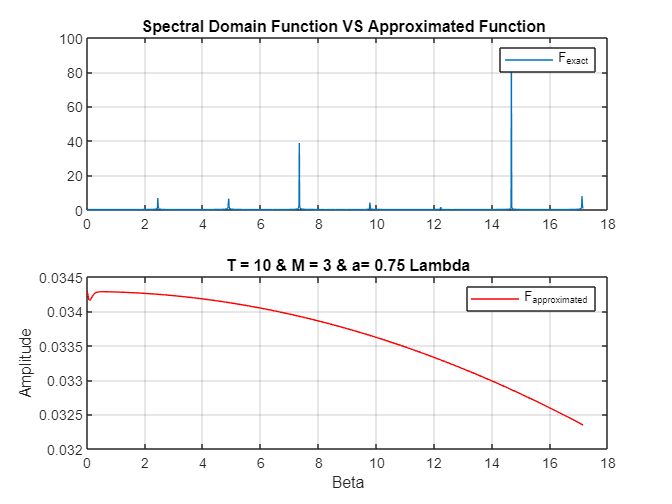

Plott_Compare(Solution_4.Beta,Solution_4.F_exact,Solution_4.F_approx,Solution_4.T,Solution_4.a,Solution_4.Lambda,Solution_4.M)

function Plott_Compare(Beta,F_exact,F_approx,T,a,Lambda,M)

figure()
subplot(2,1,1)
plot(Beta  , abs(F_exact))
legend("F_{exact}")
title("Spectral Domain Function VS Approximated Function  ")
grid on
subplot(2,1,2)

plot(Beta  , abs(F_approx),'r')
xlabel("Beta")
legend( "F_{approximated}")
grid on
ylabel("Amplitude")
title("T = "+T+" & M = "+M+" & a= "+a/Lambda+" Lambda")

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function F_approx = F_approx_calc(Beta,z_point,z_point_source,A,B_m)
syms Beta_z
F_tilde_approx(Beta_z) = reshape(A,1,[])*exp(B_m*Beta_z);

% a= 0.3429;
% syms Beta_z
% F(Beta_z)  =  exp(-1j*Beta_z*2*a) ./ ( 1- exp(-1j*Beta_z*2*a) )  ; 

F_approx = 1./(2j*Beta) .* ( exp(-1j*Beta*(z_point - z_point_source))-exp(-1j*Beta*(z_point + z_point_source))+double(F_tilde_approx(Beta)).*...
    ( exp(-1j*Beta*(z_point - z_point_source))-exp(-1j*Beta*(z_point + z_point_source))+exp(-1j*Beta*(-z_point + z_point_source))-...
    exp(-1j*Beta*(-z_point - z_point_source))  )     ) ;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function F_exact = F_exact_calc(Beta,z_point,z_point_source,a)

syms Beta_z
F(Beta_z)  =  exp(-1j*Beta_z*2*a) ./ ( 1- exp(-1j*Beta_z*2*a) )  ; 

F_exact = 1./(2j*Beta) .* ( exp(-1j*Beta*(z_point - z_point_source))-exp(-1j*Beta*(z_point + z_point_source))+double(F(Beta)).*...
    ( exp(-1j*Beta*(z_point - z_point_source))-exp(-1j*Beta*(z_point + z_point_source))+exp(-1j*Beta*(-z_point + z_point_source))-...
    exp(-1j*Beta*(-z_point - z_point_source))  )     ) ;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function Object_out  = Prony_calc(M,T,a,K)

syms Beta_z
F(Beta_z)  =  exp(-1j*Beta_z*2*a) ./ ( 1- exp(-1j*Beta_z*2*a) )  ; 

t  = linspace(0,T,2*M); 
L1 = length(t);

B_Z = K*( (1-t/T) - 1j*t  ) ;

for i=1:L1
    F_B_z  =  double( F(B_Z) ) ;
end

Out_object= Prony_Main(M,F_B_z,B_Z);

A = Out_object.A;
B_m = Out_object.B_m;
Mu = Out_object.Mu; 
Alpha = Out_object.Alpha ;

Object_out.K = K;
Object_out.Alpha = Alpha;
Object_out.Mu = Mu;
Object_out.M = M;
Object_out.T = T;
Object_out.A    =  A;
Object_out.B_m  = B_m;

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function Out_object= Prony_Main(M,F_B_z,X_vec)

Coeff_Alpha = zeros(M,M);

for p=1:M

    Coeff_Alpha(p,:) = flip(F_B_z(1+p-1:M+p-1)) ;

end
Sampled_Points = reshape(F_B_z(M+1:2*M),[],1) ;
Alpha          = -inv(Coeff_Alpha)*  Sampled_Points  ;


Mu = roots([1 ; Alpha]);
B_m  = log(Mu);

Coeff_A = zeros(M,M);

for p=1:M
    Coeff_A(p,:) = (Mu.^(p-1)).*ones(M,1) ;
end

Sampled_Points_2 = reshape(F_B_z(1:M),[],1); 
A = inv(Coeff_A) * Sampled_Points_2;

Out_object.A =A;
Out_object.B_m =B_m;
Out_object.Mu = Mu;
Out_object.Alpha = Alpha;


end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function Solution_1 = Solution_calc(M,T,a,K,Lambda,z_point,z_point_source,Beta)

Solution_1  = Prony_calc(M,T,a,K);
A = Solution_1.A ;
B_m = Solution_1.B_m;

F_exact = F_exact_calc(Beta,z_point,z_point_source,a);
F_approx = F_approx_calc(Beta,z_point,z_point_source,A,B_m);



Solution_1.z_point = z_point;
Solution_1.z_point_source = z_point_source;
Solution_1.Beta = Beta;
Solution_1.F_exact = F_exact;
Solution_1.F_approx = F_approx;
Solution_1.Lambda = Lambda;
Solution_1.a =a;


end